load('C:\Users\Asus\Desktop\data_A')


x=data_noise(1:1000,1:11);
y=data_noise(1:1000,12);
rng('default');
cv = cvpartition(size(x,1),'HoldOut',0.3);
idx = cv.test;
% Separate to training and test data
x_train = x(~idx,:);
x_test  = x(idx,:);
y_train = y(~idx,:);
y_test  = y(idx,:);  

% % I3 - find the best alpha
% i=1;
% teta_optimal=zeros(5,100);
% for alpa=0.01:0.01:1
%     cvx_begin 
%         variable teta_3(5,1);
%         minimize((y_train-x_train*teta_3)'*(y_train-x_train*teta_3)+alpa*(teta_3(1:3,1)'*teta_3(1:3,1)));
%     cvx_end
%     teta_optimal(:,i)=teta_3;
%     i=i+1;
% end

% u=0.01;
% error=[];
% for i=1:100
%     error(i)=(y_test-x_test*teta_optimal(:,i))'*(y_test-x_test*teta_optimal(:,i))+u*(teta_optimal(1:3,i)'*teta_optimal(1:3,i));
%     u=u+0.01;
% end
% plot(0.01:0.01:1,error);
% grid

% I3
% alpha=1;
alpha=10;

    cvx_begin 
        variable teta_3(11,1);
        minimize((y_train-x_train*teta_3)'*(y_train-x_train*teta_3)+alpha*(teta_3(1:4,1)'*teta_3(1:4,1)));
    cvx_end

 
Calling SDPT3 4.0: 708 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  = 708,   num. of socp blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.1e+01|1.7e+00|2.0e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.997|0.972|3.1e-02|5.0e-02|5.3e+02| 1.049695e+02 -8.905560e+01| 0:0:00| chol  1  1 
 2|1.000|0.873|3.6e-05|8.4e-03|9.8e+01| 3.263152e+01 -3.240319e+01| 0:0:00| chol  1  1 
 3|0.951|0.989|2.5e-05|1.2e-04|7.4e+00|-1.590009e+01 -2.14288

teta=teta_3

teta = 	1.0e+05 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0261
   -0.2093
    0.7222
   -1.3399
    1.3957
   -0.7699


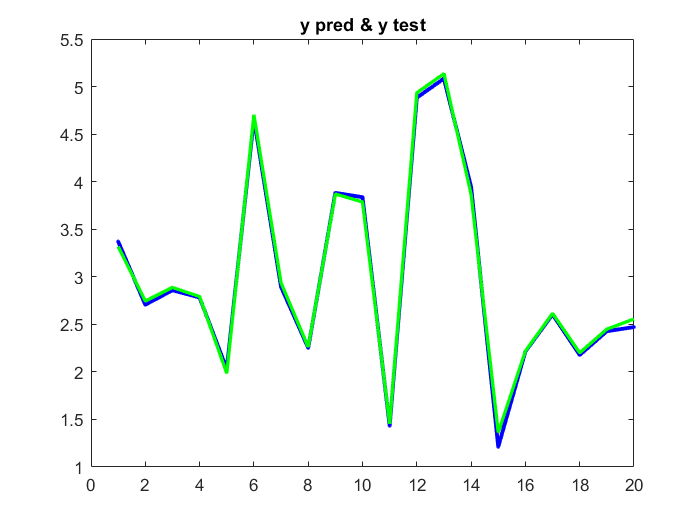

y_pred_train=x_train*teta;
   y_pred=x_test*teta;
   
   MSE = mean((y_pred - y_test).^2);
   MSE_test = MSE;
   
   MSE1 = mean((y_pred_train - y_train).^2);
   MSE_train = MSE1;
   
   errors =  y_test - y_pred;
   error_test=errors;
   
   errors1 =  y_train - y_pred_train;
   error_train=errors1;
   
   MAE = mean(abs(y_pred - y_test));
   MAE_test = MAE;

   MAE1 = mean((y_pred_train - y_train).^2);
   MAE_train = MAE1;
   
   
% subplot_rows = 3;
% subplot_cols = 4;
% 
%     % Generate the plot for the current i
% subplot(subplot_rows, subplot_cols, i);
u = x_test(:, 2);
cov_teta_hat = ((errors' * errors) * (x_train' * x_train)^-1)/(700-11);
errbar = sqrt(diag(x_test * cov_teta_hat * x_test'));






plot(y_pred(1:20,:),'.-b','linewidth',2.3);
hold on
plot(y_test(1:20,:),'-g','linewidth',2);
title("y pred & y test");
 hold off 

 
%  subplot(subplot_rows, subplot_cols, i);
% plot(y_pred,'.-b','linewidth',2.3);
% hold on
% plot(y_test,'-g','linewidth',2);
% title("y pred & y test");
%  hold off 
%  
 
 
 

ghodrat_noise=errors.'*errors/(700-11);
deghat_takhmin=cov(teta);
deghat_model=MSE;

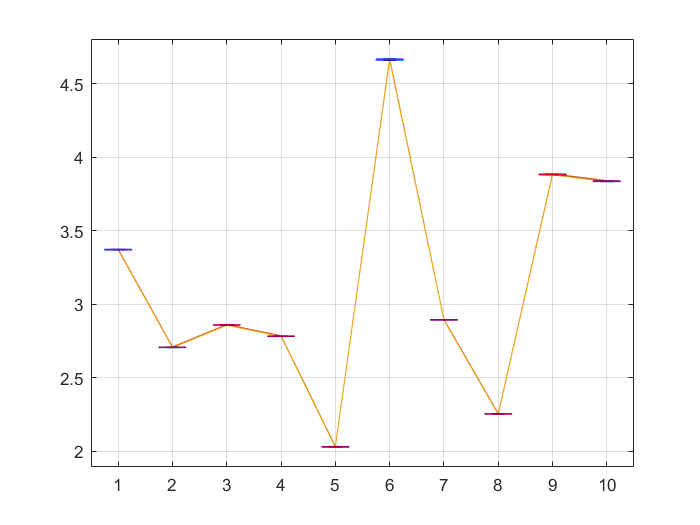

    
u1=1:1:10;
plot((y_pred(1:10,:)),'-');
hold on
plot((y_pred(1:10,:)+errbar(1:10,:)));
hold on
plot((y_pred(1:10,:)-errbar(1:10,:)));
grid

x=sort(u1).';
y=sort(y_pred(1:10,:)).';
data = [((y_pred(1:10,:))-errbar(1:10,:)).'; (y_pred(1:10,:)).'; ((y_pred(1:10,:))+errbar(1:10,:)).'];

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.5);
hold off

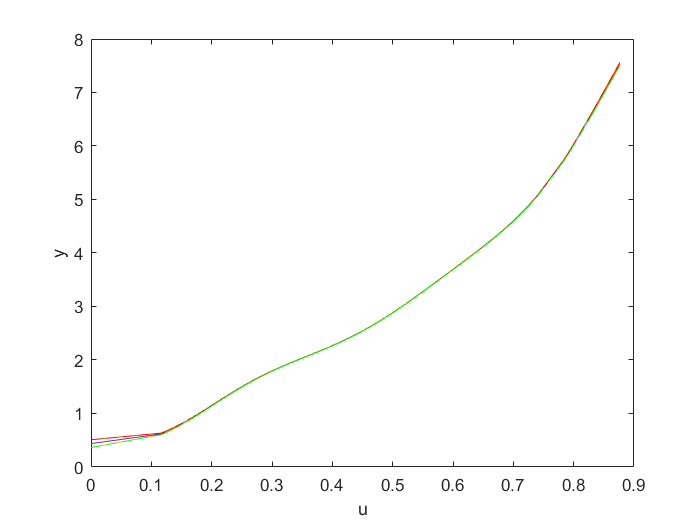

    upper_bound=y_pred + errbar;
    lower_bound=y_pred - errbar;
    
   [a_sorted, sort_idx] = sort(u);
b_sorted = y_pred(sort_idx);
c_sorted =upper_bound(sort_idx);
d_sorted =lower_bound(sort_idx);
% CI_low_sorted=CI_low(sort_idx)
% CI_high_sorted=CI_high(sort_idx)


plot(a_sorted, b_sorted, '-');
hold on;
plot(a_sorted, c_sorted, '-');
hold on
plot(a_sorted, d_sorted, '-');
hold on
% plot(a_sorted, CI_low_sorted, '-');
% hold on
% plot(a_sorted, CI_high_sorted, '-');
% hold on

for j = 1:length(a_sorted)-1
    x = [a_sorted(j), a_sorted(j+1)];
    y = [b_sorted(j), b_sorted(j+1)];
    plot(x, y);
    hold on
    xx = [a_sorted(j), a_sorted(j+1)];
    yy = [c_sorted(j), c_sorted(j+1)];
    plot(xx, yy, 'r--');
     hold on
    xxx = [a_sorted(j), a_sorted(j+1)];
    yyy = [d_sorted(j), d_sorted(j+1)];
    plot(xxx, yyy, 'g--');
%          hold on
%     xxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyy = [CI_low_sorted(j), CI_low_sorted(j+1)];
%     plot(xxxx, yyyy, 'g--');
%          hold on
%     xxxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyyy = [CI_high_sorted(j), CI_high_sorted(j+1)];
%     plot(xxxxx, yyyyy, 'g--');
end
    xlabel('u');
    ylabel('y');


    % Set subplot title

    hold off

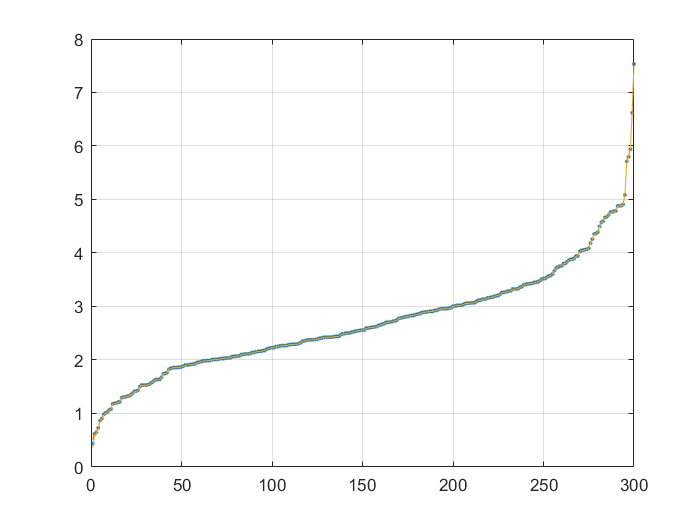

figure;
plot(sort(y_pred),'.');
hold on
plot(sort(y_pred+errbar));
hold on
plot(sort(y_pred-errbar));
grid

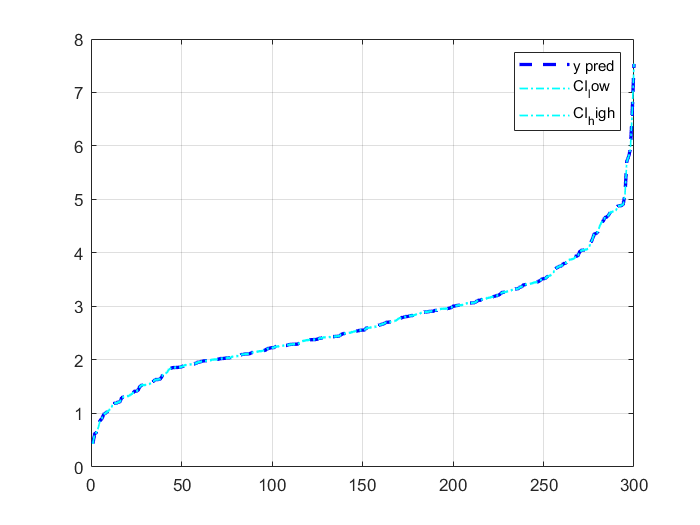

% Calculate the confidence interval
CI = 1.96 * std(errors) / sqrt(length(errors));
CI_low = y_pred - CI;
CI_high = y_pred + CI;

% Plot 
figure
plot(sort(y_pred), '--b', 'LineWidth', 2)
hold on
plot(sort(CI_low), '-.c', 'LineWidth', 1)
hold on
plot(sort(CI_high), '-.c', 'LineWidth', 1)
grid
legend('y pred', 'CI_low', 'CI_high')
hold off

disp('Ghodrat Noise');

Ghodrat Noise


disp(ghodrat_noise);

    0.0017




disp('Deghat Takhmin');

Deghat Takhmin


disp(deghat_takhmin);

   4.9326e+09




disp('Deghat Model / Mean Square Error');

Deghat Model / Mean Square Error


disp(deghat_model);

    0.0040

